# Voltage clamp recordings for moving bar stimulus

ups = grabFromFilter('UP Cells');
downs = grabFromFilter('DOWN Cells');

us = {};
ds = {};

orientations = [0:45:315];
upPeakEx = cell(numel(orientations), 1);
upChargeEx = cell(numel(orientations), 1);
upPeakInh = cell(numel(orientations), 1);
upChargeInh = cell(numel(orientations), 1);
upCoordsEx = zeros(0, 2);
upCoordsInh = zeros(0, 2);


downPeakEx = cell(numel(orientations), 1);
downChargeEx = cell(numel(orientations), 1);
downPeakInh = cell(numel(orientations), 1);
downChargeInh = cell(numel(orientations), 1);
downCoordsEx = zeros(0, 2);
downCoordsInh = zeros(0, 2);


%choose which protocols to look at
priorityOrder_1 = {'Moving_Bar'}; %first field name should be one of these. Priority is in given order
priorityOrder_2 = {'Intracellular'}; %child field name should be one of these. Priority is in given order
mustHave_1 = [];
mustHave_2 = {'_ff', 'Intracellular', 'Excitation'};
mustHave_2b = {'_ff', 'Intracellular', 'Inhibition'};
cantHave_1 = [];
cantHave_2 = {'Extracellular', 'CurrentClamp'}; %avoid anything with these tags
rigMandates = []; %use only cells with LED spot diameter = 500

%ups first
for i = 1:size(ups, 1)
    struct_i = ups{i, 2};
    
    [loc_excitation, pass1] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    [loc_inhibition, pass2] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2b, cantHave_2, rigMandates);
    if ~pass1 || ~pass2
        %         disp([struct_i.cellID, struct_i.Tags])
        us(end+1, :) = ups(i, :);
    end
    
    try
    polCoords = struct_i.coordinates.polar;
    [x, y] = pol2cart(polCoords(1), polCoords(2));
    coords = [-x, y];
    catch
        continue
    end
    if ~pass1
        loc = loc_excitation;
        for j = 1:numel(orientations)
            indices = loc.Analysis_Results.orientationByEpoch  == orientations(j);
            upPeakEx{j} = [upPeakEx{j}, mean(loc.Analysis_Results.maxNegativePeakByEpoch(indices))];
            upChargeEx{j} =  [upChargeEx{j}, mean(loc.Analysis_Results.TotalChargeByEpoch(indices))];
        end
        upCoordsEx = [upCoordsEx;coords];
    end
    
    if ~pass2
        loc = loc_inhibition;
        for j = 1:numel(orientations)
            indices = loc.Analysis_Results.orientationByEpoch  == orientations(j);
            upPeakInh{j} = [upPeakInh{j}, mean(loc.Analysis_Results.maxPositivePeakByEpoch(indices))];
            upChargeInh{j} =  [upChargeInh{j}, mean(loc.Analysis_Results.TotalChargeByEpoch(indices))];
        end
        upCoordsInh = [upCoordsInh;coords];
    end
end
%downs second
for i = 1:size(downs, 1)
    struct_i = downs{i, 2};
    
    [loc_excitation, pass1] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    [loc_inhibition, pass2] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2b, cantHave_2, rigMandates);
    if ~pass1 || ~pass2
        %disp([struct_i.cellID, struct_i.Tags])
        ds(end + 1,:) = downs(i, :);
    end
    
    polCoords = struct_i.coordinates.polar;
    [x, y] = pol2cart(polCoords(1), polCoords(2));
    coords = [-x, y];
    
    if ~pass1
        loc = loc_excitation;
        for j = 1:numel(orientations)
            indices = loc.Analysis_Results.orientationByEpoch  == orientations(j);
            downPeakEx{j} = [downPeakEx{j}, mean(loc.Analysis_Results.maxNegativePeakByEpoch(indices))];
            downChargeEx{j} =  [downChargeEx{j}, mean(loc.Analysis_Results.TotalChargeByEpoch(indices))];
        end
        downCoordsEx = [downCoordsEx;coords];
    end
    
    if ~pass2
        loc = loc_inhibition;
        for j = 1:numel(orientations)
            indices = loc.Analysis_Results.orientationByEpoch  == orientations(j);
            downPeakInh{j} = [downPeakInh{j}, mean(loc.Analysis_Results.maxPositivePeakByEpoch(indices))];
            downChargeInh{j} =  [downChargeInh{j}, mean(loc.Analysis_Results.TotalChargeByEpoch(indices))];
        end
        downCoordsInh = [downCoordsInh;coords];
    end
end

## Tuning Curves

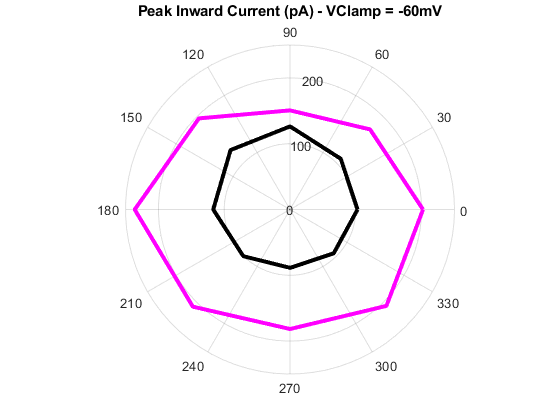

upPeakExMean = averageOfCellArray(upPeakEx)';
upChargeExMean = averageOfCellArray(upChargeEx)';
upPeakInhMean = averageOfCellArray(upPeakInh)';
upChargeInhMean = averageOfCellArray(upChargeInh)';

downPeakExMean = averageOfCellArray(downPeakEx)';
downChargeExMean = averageOfCellArray(downChargeEx)';
downPeakInhMean = averageOfCellArray(downPeakInh)';
downChargeInhMean = averageOfCellArray(downChargeInh)';

angles = deg2rad(orientations);
angles = [angles, angles(1)];

%excitatory tuning curves
figure()
polarplot(angles, -[upPeakExMean, upPeakExMean(1)], 'k', 'LineWidth', 3)
hold on
polarplot(angles, -[downPeakExMean, downPeakExMean(1)], 'm', 'LineWidth', 3)
title('Peak Inward Current (pA) - VClamp = -60mV')

[upPeakExDSI, upPeakExVector] = calculateDSI(orientations, -upPeakExMean)

upPeakExDSI = 0.0865

upPeakExVector =   115.1890   74.8300


[downPeakExDSI, downPeakExVector] = calculateDSI(orientations, -downPeakExMean)

downPeakExDSI = 0.0535

downPeakExVector =  -128.5924   83.1510


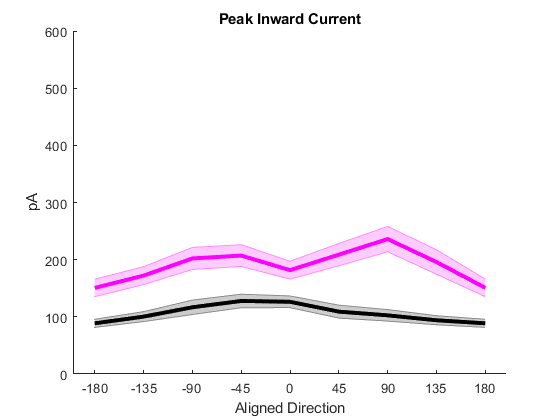

ps = zeros(1, numel(orientations));
ms = zeros(2, numel(orientations));
es = zeros(2, numel(orientations));
dRotated = [downPeakEx(5:8); downPeakEx(1:4)];

allUpPeakEx = zeros(numel(upPeakEx{1}), numel(orientations));
allDownPeakEx = zeros(numel(downPeakEx{1}), numel(orientations));

for i = 1:numel(orientations)
    dGroup = dRotated{i};
    uGroup = upPeakEx{i};
    ps(i) = ranksum(dGroup, uGroup);
    ms(1, i) = -mean(uGroup);
    ms(2, i) = -mean(dGroup);
    es(1, i) = std(uGroup)/sqrt(numel(uGroup));
    es(2, i) = std(dGroup)/sqrt(numel(dGroup));
    
    allUpPeakEx(:, i) = uGroup;
    allDownPeakEx(:, i) = dGroup;
end

% figure
% title('Peak Inward Current')
% hold on
% errorbar(orientations, ms(1, :), es(1, :), 'k', 'LineWidth', 3)
% errorbar(orientations, ms(2, :), es(2, :), 'm', 'LineWidth', 3)
% ylabel('pA')
% xlabel('Aligned Direction')'
curveOrientations = [-180:45:180];
figure
title('Peak Inward Current')
hold on
shadedErrorBar(curveOrientations, ms(1, [7:-1:1, 8, 7]), es(1, [7:-1:1, 8, 7]), 'LineProps', {'k', 'LineWidth', 3})
shadedErrorBar(curveOrientations, ms(2,[7:-1:1, 8,  7]), es(2, [7:-1:1, 8, 7]), 'LineProps', {'m', 'LineWidth', 3})
ylabel('pA')
xlabel('Aligned Direction')
xticks([-180:45:180])
ylim([0 600])

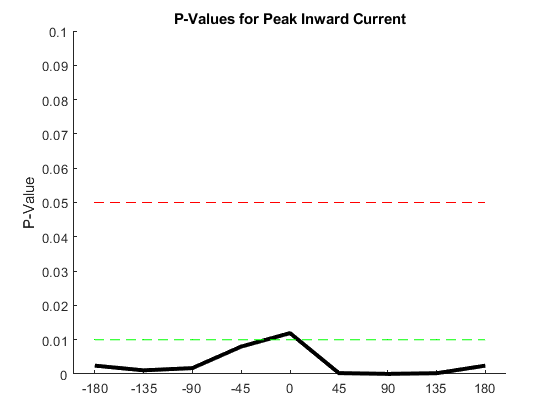

%this little bit is to save variables for another script that calls on this
%file to get some analysis... don't worry about these variables but don't
%delete them:
upExMs = ms(1, :);
upExEs = es(1, :);
downExMs = ms(2, :);
downExEs = es(2, :);

figure
title('P-Values for Peak Inward Current')
hold on
plot(curveOrientations, [ps([7:-1:1, 8, 7])], 'k', 'linewidth', 3)
plot(curveOrientations, zeros(size(curveOrientations))+0.01, '--g')
plot(curveOrientations, zeros(size(curveOrientations))+0.05, '--r')
ylim([0, 0.1])
ylabel('P-Value')
xticks([-180:45:180])


ps = [ps(7:8), ps(1:7)]

ps =     0.0024    0.0002    0.0000    0.0003    0.0119    0.0080    0.0017    0.0011    0.0024


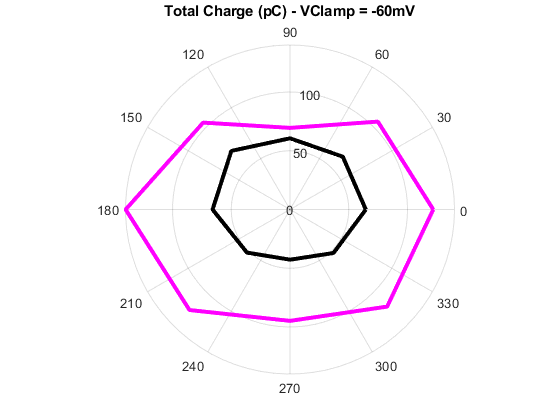

figure()
polarplot(angles, -[upChargeExMean, upChargeExMean(1)], 'k', 'LineWidth', 3)
hold on
polarplot(angles, -[downChargeExMean, downChargeExMean(1)], 'm', 'LineWidth', 3)
title('Total Charge (pC) - VClamp = -60mV')

[upChargeExDSI, upChargeExVector] = calculateDSI(orientations, -upChargeExMean)

upChargeExDSI = 0.0837

upChargeExVector =    98.7805   39.4939


[downChargeExDSI, downChargeExVector] = calculateDSI(orientations, -downChargeExMean)

downChargeExDSI = 0.0561

downChargeExVector =  -114.1515   49.0720


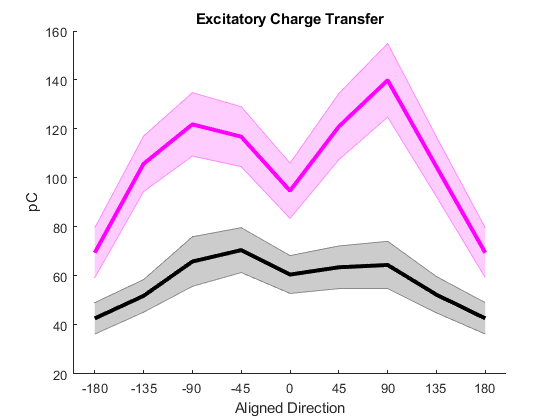

ps = zeros(1, numel(orientations));
ms = zeros(2, numel(orientations));
es = zeros(2, numel(orientations));
dRotated = [downChargeEx(5:8); downChargeEx(1:4)];
for i = 1:numel(orientations)
    dGroup = dRotated{i};
    uGroup = upChargeEx{i};
    ps(i) = ranksum(dGroup, uGroup);
    ms(1, i) = -mean(uGroup);
    ms(2, i) = -mean(dGroup);
    es(1, i) = std(uGroup)/sqrt(numel(uGroup));
    es(2, i) = std(dGroup)/sqrt(numel(dGroup));
end

curveOrientations = [-180:45:180];
figure
title('Excitatory Charge Transfer')
hold on
shadedErrorBar(curveOrientations, ms(1, [7:-1:1, 8, 7]), es(1, [7:-1:1, 8, 7]), 'LineProps', {'k', 'LineWidth', 3})
shadedErrorBar(curveOrientations, ms(2, [7:-1:1, 8, 7]), es(2, [7:-1:1, 8, 7]), 'LineProps', {'m', 'LineWidth', 3})
ylabel('pC')
xlabel('Aligned Direction')
xticks([-180:45:180])

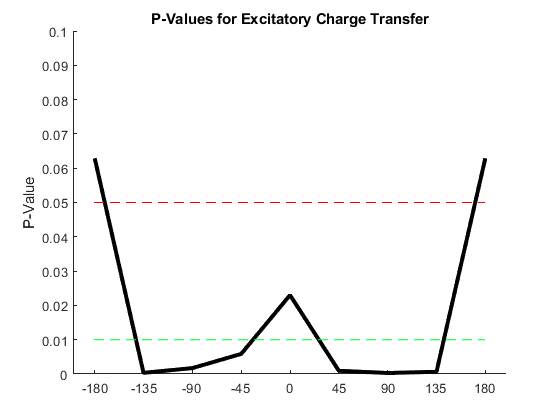

figure
title('P-Values for Excitatory Charge Transfer')
hold on
plot(curveOrientations, ps([7:-1:1, 8, 7]), 'k', 'linewidth', 3)
plot(curveOrientations, zeros(size(curveOrientations))+0.01, '--g')
plot(curveOrientations, zeros(size(curveOrientations))+0.05, '--r')
ylim([0, 0.1])
ylabel('P-Value')
xticks([-180:45:180])


ps = ps([7:-1:1, 8, 7])

ps =     0.0629    0.0003    0.0017    0.0059    0.0230    0.0009    0.0003    0.0006    0.0629


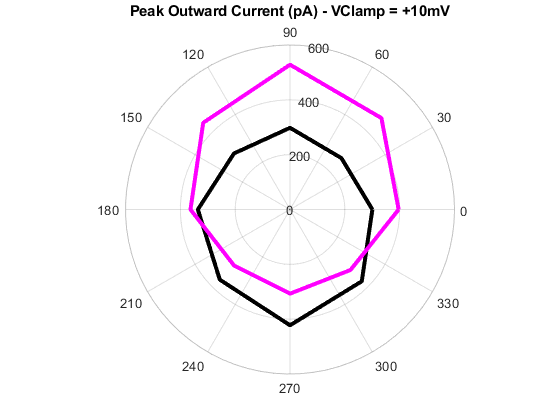


figure()
polarplot(angles, [upPeakInhMean, upPeakInhMean(1)], 'k', 'LineWidth', 3)
hold on
polarplot(angles, [downPeakInhMean, downPeakInhMean(1)], 'm', 'LineWidth', 3)
title('Peak Outward Current (pA) - VClamp = +10mV')

[upPeakInhDSI, upPeakInhVector] = calculateDSI(orientations, upPeakInhMean)

upPeakInhDSI = 0.0963

upPeakInhVector =  -100.6218  254.4510


[downPeakInhDSI, downPeakInhVector] = calculateDSI(orientations, downPeakInhMean)

downPeakInhDSI = 0.1449

downPeakInhVector =    81.5222  451.3838


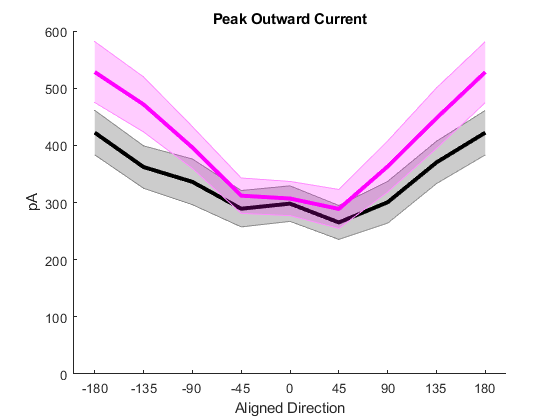


ps = zeros(1, numel(orientations));
dRotated = [downPeakInh(5:8); downPeakInh(1:4)];
ms = zeros(2, numel(orientations));
es = zeros(2, numel(orientations));
allUpPeakInh = zeros(numel(upPeakInh{1}), numel(orientations));
allDownPeakInh = zeros(numel(downPeakInh{1}), numel(orientations));

for i = 1:numel(orientations)
    dGroup = dRotated{i};
    uGroup = upPeakInh{i};
    ps(i) = ranksum(dGroup, uGroup);
    ms(1, i) = mean(uGroup);
    ms(2, i) = mean(dGroup);
    es(1, i) = std(uGroup)/sqrt(numel(uGroup));
    es(2, i) = std(dGroup)/sqrt(numel(dGroup));
    
    allUpPeakInh(:, i) = uGroup;
    allDownPeakInh(:, i) = dGroup;
end

curveOrientations = [-180:45:180];
figure
title('Peak Outward Current')
hold on
shadedErrorBar(curveOrientations, ms(1, [7:-1:1, 8, 7]), es(1, [7:-1:1, 8, 7]), 'LineProps', {'k', 'LineWidth', 3})
shadedErrorBar(curveOrientations, ms(2, [7:-1:1, 8, 7]), es(2,[7:-1:1, 8, 7]), 'LineProps', {'m', 'LineWidth', 3})
ylabel('pA')
xlabel('Aligned Direction')
xticks([-180:45:180])
ylim([0 600])

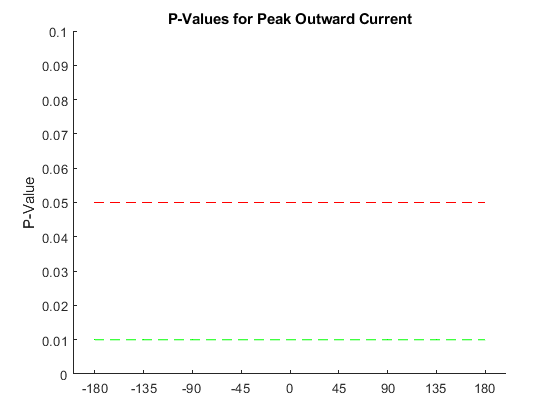

%this little bit is to save variables for another script that calls on this
%file to get some analysis... don't worry about these variables but don't
%delete them:
upInMs = ms(1, :);
upInEs = es(1, :);
downInMs = ms(2, :);
downInEs = es(2, :);



figure
title('P-Values for Peak Outward Current')
hold on
plot(curveOrientations, ps([7:-1:1, 8, 7]), 'k', 'linewidth', 3)
plot(curveOrientations, zeros(size(curveOrientations))+0.01, '--g')
plot(curveOrientations, zeros(size(curveOrientations))+0.05, '--r')
ylim([0, 0.1])
ylabel('P-Value')
xticks([-180:45:180])


ps = ps([7:-1:1, 8, 7])

ps =     0.1002    0.1402    0.2551    0.5091    0.7895    0.5838    0.2551    0.3612    0.1002


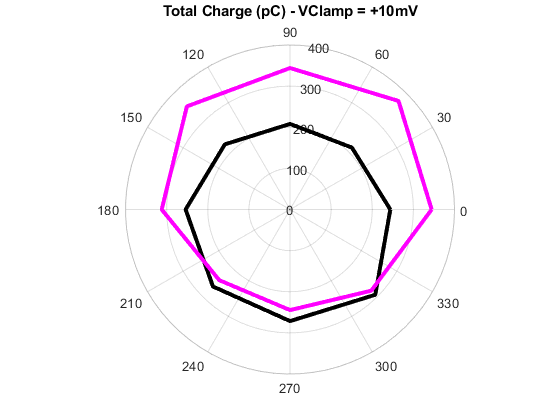


figure()
polarplot(angles, [upChargeInhMean, upChargeInhMean(1)], 'k', 'LineWidth', 3)
hold on
polarplot(angles, [downChargeInhMean, downChargeInhMean(1)], 'm', 'LineWidth', 3)
title('Total Charge (pC) - VClamp = +10mV')

[upChargeInhDSI, upChargeInhVector] = calculateDSI(orientations, upChargeInhMean)

upChargeInhDSI = 0.0755

upChargeInhVector =   -89.1659  148.9175


[downChargeInhDSI, downChargeInhVector] = calculateDSI(orientations, downChargeInhMean)

downChargeInhDSI = 0.1021

downChargeInhVector =    73.8069  254.8116


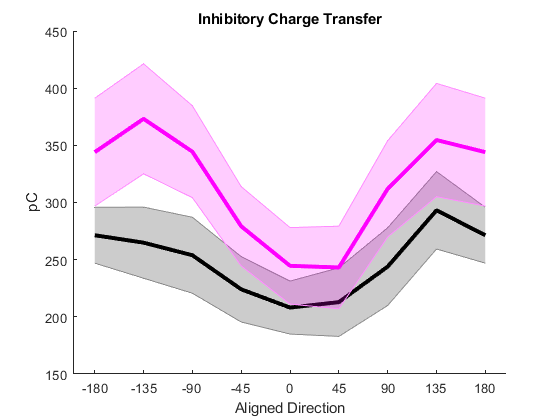

ps = zeros(1, numel(orientations));
ms = zeros(2, numel(orientations));
es = zeros(2, numel(orientations));
dRotated = [downChargeInh(5:8); downChargeInh(1:4)];
for i = 1:numel(orientations)
    dGroup = dRotated{i};
    uGroup = upChargeInh{i};
    ps(i) = ranksum(dGroup, uGroup);
    ms(1, i) = mean(uGroup);
    ms(2, i) = mean(dGroup);
    es(1, i) = std(uGroup)/sqrt(numel(uGroup));
    es(2, i) = std(dGroup)/sqrt(numel(dGroup));
end

curveOrientations = [-180:45:180];
figure
title('Inhibitory Charge Transfer')
hold on
shadedErrorBar(curveOrientations, ms(1, [7:-1:1, 8, 7]), es(1, [7:-1:1, 8, 7]), 'LineProps', {'k', 'LineWidth', 3})
shadedErrorBar(curveOrientations, ms(2, [7:-1:1, 8, 7]), es(2, [7:-1:1, 8, 7]), 'LineProps', {'m', 'LineWidth', 3})
ylabel('pC')
xlabel('Aligned Direction')
xticks([-180:45:180])

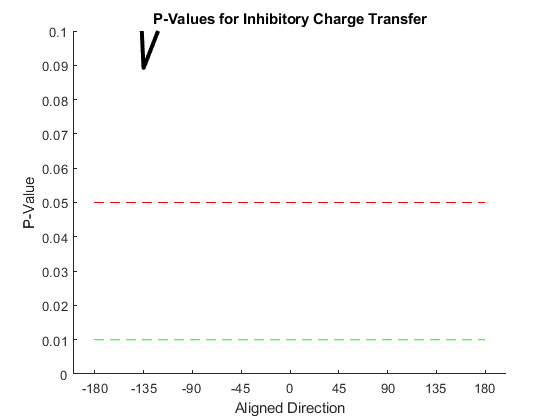


figure
title('P-Values for Inhibitory Charge Transfer')
hold on
plot(curveOrientations, ps([7:-1:1, 8, 7]), 'k', 'linewidth', 3)
plot(curveOrientations, zeros(size(curveOrientations))+0.01, '--g')
plot(curveOrientations, zeros(size(curveOrientations))+0.05, '--r')
ylim([0, 0.1])
ylabel('P-Value')
xlabel('Aligned Direction')
xticks([-180:45:180])


p = ps([7:-1:1, 8, 7])

p =     0.3915    0.0891    0.1257    0.2551    0.5646    0.5838    0.2324    0.5458    0.3915


## Ratio of down to up

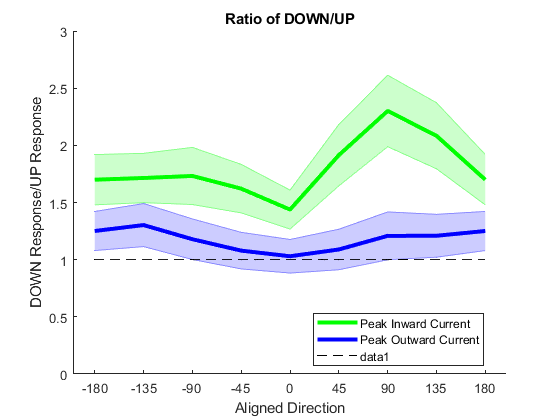

% all plots as down cells/up cells (note, I've been looking at means so far, not sure if means or medians is better)
upPeakExReorganized = allUpPeakEx(:, [7:-1:1, 8, 7]);
downPeakExReorganized = allDownPeakEx(:, [7:-1:1, 8, 7]);

semUpPeakExReorganized = std(upPeakExReorganized)/sqrt(size(upPeakExReorganized, 1));
semDownPeakExReorganized = std(downPeakExReorganized)/sqrt(size(downPeakExReorganized, 1));

propogatedErrorEx = sqrt((semUpPeakExReorganized./mean(upPeakExReorganized)).^2 + ...
    (semDownPeakExReorganized./mean(downPeakExReorganized)).^2)...
    .*mean(downPeakExReorganized)./mean(upPeakExReorganized);


upPeakInhReorganized = allUpPeakInh(:, [7:-1:1, 8, 7]);
downPeakInhReorganized = allDownPeakInh(:, [7:-1:1, 8, 7]);

semUpPeakInhReorganized = std(upPeakInhReorganized)/sqrt(size(upPeakInhReorganized, 1));
semDownPeakInhReorganized = std(downPeakInhReorganized)/sqrt(size(downPeakInhReorganized, 1));

propogatedErrorInh = sqrt((semUpPeakInhReorganized./mean(upPeakInhReorganized)).^2 + ...
    (semDownPeakInhReorganized./mean(downPeakInhReorganized)).^2)...
    .*mean(downPeakInhReorganized)./mean(upPeakInhReorganized);

%use a permutation test to get the p-values of ratio of medians
trueRatiosEx = median(downPeakExReorganized)./median(upPeakExReorganized);
trueRatiosInh = median(downPeakInhReorganized)./median(upPeakInhReorganized);

trueRatioDifferences = trueRatiosEx - trueRatiosInh;

reps = 10000;
responses = zeros(reps, size(downPeakExReorganized, 2));
splitEx = round(size(downPeakExReorganized, 1));
splitInh = round(size(upPeakInhReorganized, 1));
pvalues = zeros(1, size(downPeakExReorganized, 2));
for i = 1:size(downPeakExReorganized, 2)
    allExVals = [downPeakExReorganized(:, i); upPeakExReorganized(:, i)];
    allInhVals = [downPeakInhReorganized(:, i); upPeakInhReorganized(:, i)];
    for n = 1:reps
        permEx = allExVals(randperm(numel(allExVals)));
        permInh = allInhVals(randperm(numel(allInhVals)));
        half1Ex = -permEx(1:splitEx); half2Ex = -permEx(splitEx:end);
        half1Inh = permInh(1:splitInh); half2Inh = permInh(splitInh:end);
        responses(n, i) = median(half1Ex)/median(half2Ex) - median(half1Inh)/median(half2Inh);
    end
    pvalues(i) = sum(abs(responses(:, i)) > abs(trueRatioDifferences(i)))/reps;
end

%An alternative to the permutation test is a bootstrapping method:
reps = 10000;
numUpInh = size(upPeakInhReorganized, 1);
numUpEx = size(upPeakExReorganized, 1);
numDownInh = size(downPeakInhReorganized, 1);
numDownEx = size(downPeakExReorganized, 1);
bootstrappedMedianRatios = zeros(size(downPeakExReorganized, 2), reps);
pvalues_bootstrapped = zeros(1, size(downPeakExReorganized, 2));
for i = 1:size(downPeakExReorganized, 2)
    upInh = upPeakInhReorganized(:, i);
    upEx = upPeakExReorganized(:, i);
    downInh = downPeakInhReorganized(:, i);
    downEx = downPeakExReorganized(:, i);
    for n = 1:reps
        upInhSampleIndices = randsample(numUpInh, numUpInh, true);
        upInhDist = upInh(upInhSampleIndices);
        upExSampleIndices = randsample(numUpEx, numUpEx, true);
        upExDist = upEx(upExSampleIndices);
        downInhSampleIndices = randsample(numDownInh, numDownInh, true);
        downInhDist = downInh(downInhSampleIndices);
        downExSampleIndices = randsample(numDownEx, numDownEx, true);
        downExDist = downEx(downExSampleIndices);
        
        bootstrappedMedianRatios(i, n) = median(downExDist)./median(upExDist) - median(downInhDist)./median(upInhDist);
    end
    pvalues_bootstrapped(i) = sum(bootstrappedMedianRatios(i, :) <= 0)/reps;
end


figure
title('Ratio of DOWN/UP')
hold on
shadedErrorBar(curveOrientations, mean(downPeakExReorganized)./mean(upPeakExReorganized), propogatedErrorEx,...
    'LineProps', {'g', 'LineWidth', 3})
shadedErrorBar(curveOrientations, mean(downPeakInhReorganized)./mean(upPeakInhReorganized), propogatedErrorInh,...
    'LineProps', {'b', 'LineWidth', 3})
xlabel('Aligned Direction')
ylabel('DOWN Response/UP Response')
l = legend({'Peak Inward Current', 'Peak Outward Current'});
l.Location = 'best';
xticks([-180:45:180])
ylim([0, 3])
plot([-180, 180], [1, 1], '--k')

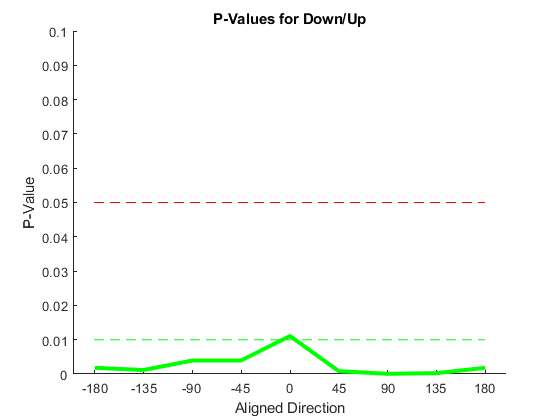

nEx = min(numel(downPeakExReorganized), numel(upPeakExReorganized));
tStatsExcitation = (mean(downPeakExReorganized)./mean(upPeakExReorganized) - 1)./propogatedErrorEx;
pExcitation = (1-tcdf(tStatsExcitation,nEx-1))*2;

nInh = min(numel(downPeakInhReorganized), numel(upPeakInhReorganized));
tStatsInhibition = (mean(downPeakInhReorganized)./mean(upPeakInhReorganized) - 1)./propogatedErrorInh;
pInhibition = (1-tcdf(tStatsInhibition,nInh-1))*2;

figure
title('P-Values for Down/Up')
hold on
plot(curveOrientations, pExcitation, 'g', 'linewidth', 3)
plot(curveOrientations, pInhibition, 'b', 'linewidth', 3)
plot(curveOrientations, zeros(size(curveOrientations))+0.01, '--g')
plot(curveOrientations, zeros(size(curveOrientations))+0.05, '--r')
ylim([0, 0.1])
ylabel('P-Value')
xlabel('Aligned Direction')
xticks([-180:45:180])


pExcitation %p values generated from t-statistic

pExcitation =     0.0018    0.0012    0.0039    0.0039    0.0111    0.0008    0.0001    0.0003    0.0018


pInhibition

pInhibition =     0.1444    0.1098    0.3153    0.6223    0.8394    0.6156    0.3206    0.2662    0.1444


## Total excitation over all directions

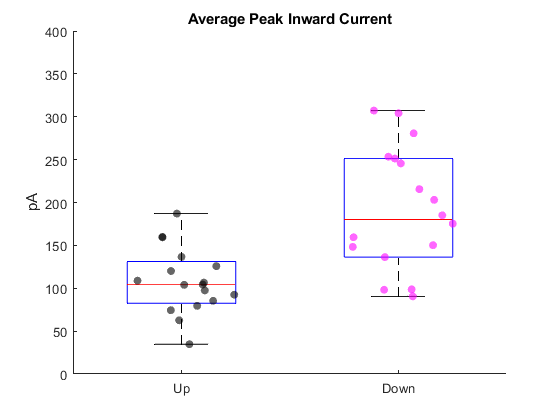

%if excitation is not tuned, it should be the same regardless of bar
%direction. Here, I take the average excitation (peak and charge) over all
%directions for each cell. Then I compare this average for up and down
%cells. (I also do the same for inhibition, but it makes less sense to do
%this since inhibition should be tuned).
numUpsEx = numel(upPeakEx{1});
numDownsEx = numel(downPeakEx{1});
numUpsInh = numel(upPeakInh{1});
numDownsInh = numel(downPeakInh{1});

upAvgsEx = zeros(2, numUpsEx);
downAvgsEx = zeros(2, numDownsEx);
for i = 1:numUpsEx
    sumPeak = 0;
    sumCharge = 0;
    for j = 1:numel(upPeakEx)
        placePeak = upPeakEx{j};
        sumPeak = sumPeak + placePeak(i);
        placeCharge = upChargeEx{j};
        sumCharge = sumCharge + placeCharge(i);
    end
    upAvgsEx(:, i) = [sumPeak; sumCharge]./j;
end

for i = 1:numDownsEx
    sumPeak = 0;
    sumCharge = 0;
    for j = 1:numel(downPeakEx)
        placePeak = downPeakEx{j};
        sumPeak = sumPeak + placePeak(i);
        placeCharge = downChargeEx{j};
        sumCharge = sumCharge + placeCharge(i);
    end
    downAvgsEx(:, i) = [sumPeak; sumCharge]./j;
end


upAvgsInh = zeros(2, numUpsInh);
downAvgsInh = zeros(2, numDownsInh);
for i = 1:numUpsInh
    sumPeak = 0;
    sumCharge = 0;
    for j = 1:numel(upPeakInh)
        placePeak = upPeakInh{j};
        sumPeak = sumPeak + placePeak(i);
        placeCharge = upChargeInh{j};
        sumCharge = sumCharge + placeCharge(i);
    end
    upAvgsInh(:, i) = [sumPeak; sumCharge]./j;
end

for i = 1:numDownsInh
    sumPeak = 0;
    sumCharge = 0;
    for j = 1:numel(downPeakInh)
        placePeak = downPeakInh{j};
        sumPeak = sumPeak + placePeak(i);
        placeCharge = downChargeInh{j};
        sumCharge = sumCharge + placeCharge(i);
    end
    downAvgsInh(:, i) = [sumPeak; sumCharge]./j;
end



allPoints = -[upAvgsEx(1, :)'; downAvgsEx(1, :)'];
groups = zeros(size(allPoints));
groups(numel(upAvgsEx(1, :)):end, 1) = 1;

figure
title ('Average Peak Inward Current')
hold on
boxplot(allPoints, groups, 'Symbol' , '', 'Widths', 0.5)
scatter(ones(1, numel(upAvgsEx(1, :))), -upAvgsEx(1, :),'filled', 'k', 'MarkerFaceAlpha',0.6, 'XJitter','density', 'XJitterWidth', 0.5)
scatter(ones(1, numel(downAvgsEx(1, :)))+1, -downAvgsEx(1, :),'filled', 'm', 'MarkerFaceAlpha',0.6, 'XJitter','density', 'XJitterWidth', 0.5)
xticks([1 , 2])
xticklabels({'Up', 'Down'})
box off
ylabel('pA')
ylim([0 400])

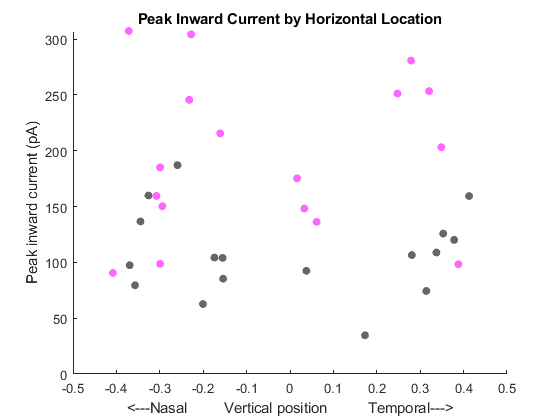

figure
title('Peak Inward Current by Horizontal Location')
hold on
scatter(upCoordsEx(:, 1), abs(upAvgsEx(1, :)), 'filled', 'k', 'MarkerFaceAlpha', 0.6)
scatter(downCoordsEx(:, 1), abs(downAvgsEx(1, :)), 'filled', 'm', 'MarkerFaceAlpha', 0.6)
ylabel('Peak inward current (pA)')
xlabel('<---Nasal         Vertical position          Temporal--->')
ylim([0 inf])

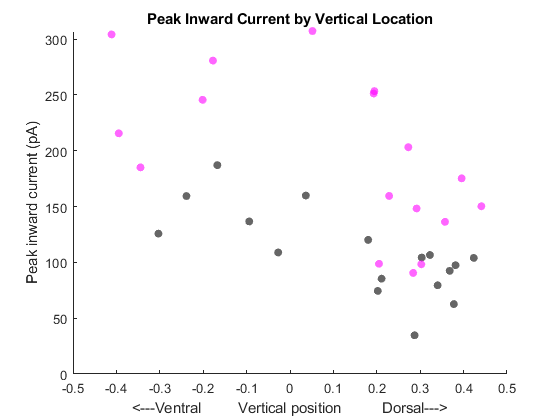


figure
title('Peak Inward Current by Vertical Location')
hold on
scatter(upCoordsEx(:, 2), abs(upAvgsEx(1, :)), 'filled', 'k', 'MarkerFaceAlpha', 0.6)
scatter(downCoordsEx(:, 2), abs(downAvgsEx(1, :)), 'filled', 'm', 'MarkerFaceAlpha', 0.6)
ylabel('Peak inward current (pA)')
xlabel('<---Ventral         Vertical position          Dorsal--->')
ylim([0 inf])

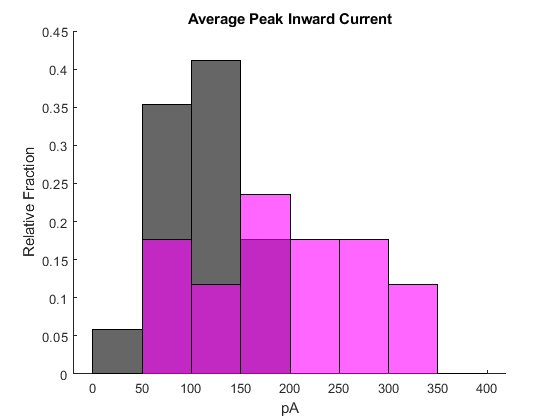


edgs= [0:50:400];
figure
title('Average Peak Inward Current')
hold on
h1 = histogram(-upAvgsEx(1, :), 'BinEdges', edgs, 'FaceColor',  'k', 'Normalization', 'probability');
h2 = histogram(-downAvgsEx(1, :), 'BinEdges', edgs, 'FaceColor', 'm', 'Normalization', 'probability');
xlabel('pA')
ylabel('Relative Fraction')

p = ranksum(upAvgsEx(1, :), downAvgsEx(1, :))

p = 7.3691e-04

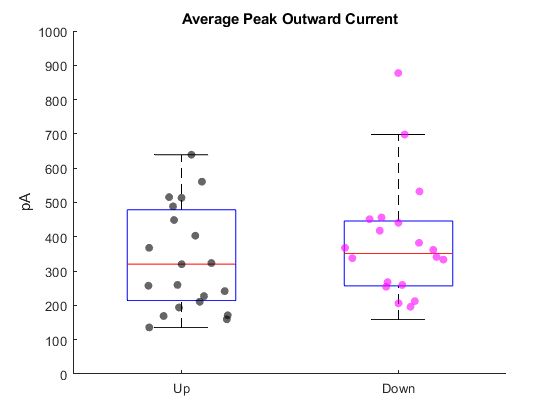

edgs= [0:50:1000];

allPoints = [upAvgsInh(1, :)'; downAvgsInh(1, :)'];
groups = zeros(size(allPoints));
groups(numel(upAvgsInh(1, :)):end, 1) = 1;

figure
title ('Average Peak Outward Current')
hold on
boxplot(allPoints, groups, 'Symbol' , '', 'Widths', 0.5)
scatter(ones(1, numel(upAvgsInh(1, :))), upAvgsInh(1, :),'filled', 'k', 'MarkerFaceAlpha',0.6, 'XJitter','density', 'XJitterWidth', 0.5)
scatter(ones(1, numel(downAvgsInh(1, :)))+1, downAvgsInh(1, :),'filled', 'm', 'MarkerFaceAlpha',0.6, 'XJitter','density', 'XJitterWidth', 0.5)
xticks([1 , 2])
xticklabels({'Up', 'Down'})
box off
ylabel('pA')
ylim([0, 1000])

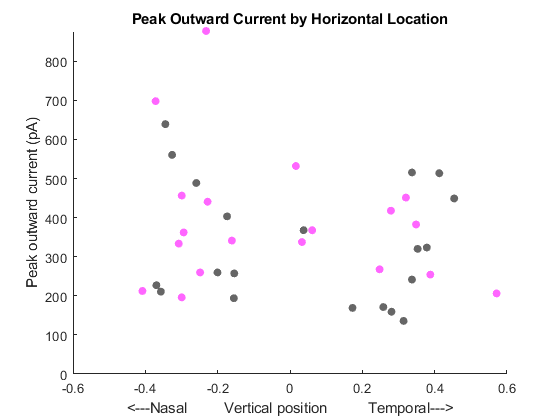

figure
title('Peak Outward Current by Horizontal Location')
hold on
scatter(upCoordsInh(:, 1), upAvgsInh(1, :), 'filled', 'k', 'MarkerFaceAlpha', 0.6)
scatter(downCoordsInh(:, 1), downAvgsInh(1, :), 'filled', 'm', 'MarkerFaceAlpha', 0.6)
ylabel('Peak outward current (pA)')
xlabel('<---Nasal         Vertical position          Temporal--->')
ylim([0 inf])

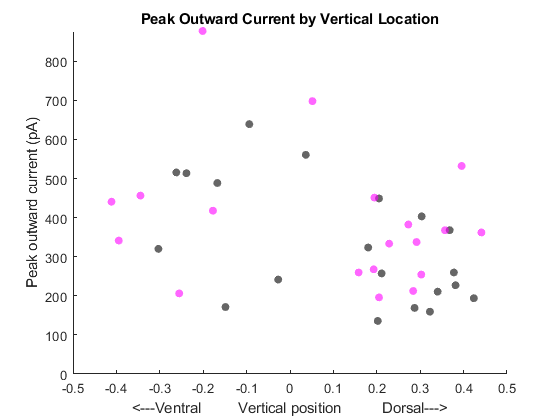


figure
title('Peak Outward Current by Vertical Location')
hold on
scatter(upCoordsInh(:, 2), upAvgsInh(1, :), 'filled', 'k', 'MarkerFaceAlpha', 0.6)
scatter(downCoordsInh(:, 2), downAvgsInh(1, :), 'filled', 'm', 'MarkerFaceAlpha', 0.6)
ylabel('Peak outward current (pA)')
xlabel('<---Ventral         Vertical position          Dorsal--->')
ylim([0 inf])

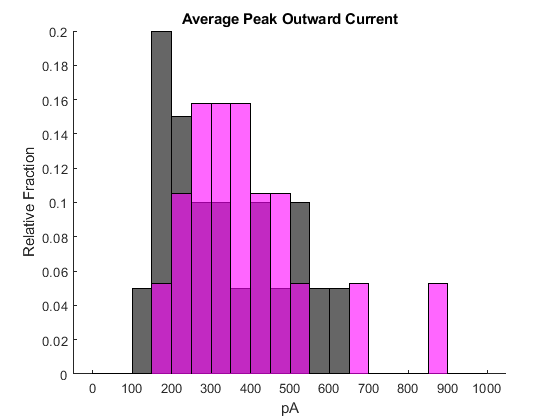


figure
title('Average Peak Outward Current')
hold on
h1 = histogram(upAvgsInh(1, :), 'BinEdges', edgs, 'FaceColor',  'k', 'Normalization', 'probability');
h2 = histogram(downAvgsInh(1, :), 'BinEdges', edgs, 'FaceColor', 'm', 'Normalization', 'probability');
xlabel('pA')
ylabel('Relative Fraction')

p = ranksum(upAvgsInh(1, :), downAvgsInh(1, :))

p = 0.2436

## DSI of excitation and inhibition for each cell

upPeakEx_DSIs = [];
for i = 1:numel(upPeakEx{1})
    curve = zeros(1, numel(orientations));
    for j = 1:size(upPeakEx, 1)
        directionResponse = -upPeakEx{j};
        curve(j) = directionResponse(i);
    end
    upPeakEx_DSIs(i) = calculateDSI(orientations, curve);
end

downPeakEx_DSIs = [];
for i = 1:numel(downPeakEx{1})
    curve = zeros(1, numel(orientations));
    for j = 1:size(downPeakEx, 1)
        directionResponse = -downPeakEx{j};
        curve(j) = directionResponse(i);
    end
    downPeakEx_DSIs(i) = calculateDSI(orientations, curve);
end

figure
title('DSIs Peak Excitation')
hold on
h1 = histogram(upPeakEx_DSIs, 'FaceColor',  'k', 'Normalization', 'probability');
h2 = histogram(downPeakEx_DSIs, 'FaceColor', 'm', 'Normalization', 'probability');
h2.BinWidth = h1.BinWidth;
xlabel('DSI of Excitation Total Charge')
ylabel('Relative Fraction')
allPoints = [upPeakEx_DSIs'; downPeakEx_DSIs'];
groups = zeros(size(allPoints));
groups(numel(upPeakEx_DSIs)+1:end, 1) = 1;

figure
title ('Peak EPSC DSI')
hold on
boxplot(allPoints, groups, 'Symbol' , '', 'Widths', 0.5)
scatter(ones(1, numel(upPeakEx_DSIs)), upPeakEx_DSIs,'filled', 'k', 'MarkerFaceAlpha',0.6, 'XJitter','density', 'XJitterWidth', 0.5)
scatter(ones(1, numel(downPeakEx_DSIs))+1, downPeakEx_DSIs,'filled', 'm', 'MarkerFaceAlpha',0.6, 'XJitter','density', 'XJitterWidth', 0.5)
ylim([0 inf])
xticklabels({'Up Cells', 'Down Cells'})
ylabel('DSI')
p = ranksum(upPeakEx_DSIs, downPeakEx_DSIs)

upChargeEx_DSIs = [];
for i = 1:numel(upChargeEx{1})
    curve = zeros(1, numel(orientations));
    for j = 1:size(upChargeEx, 1)
        directionResponse = -upChargeEx{j};
        curve(j) = directionResponse(i);
    end
    upChargeEx_DSIs(i) = calculateDSI(orientations, curve);
end

downChargeEx_DSIs = [];
for i = 1:numel(downChargeEx{1})
    curve = zeros(1, numel(orientations));
    for j = 1:size(downChargeEx, 1)
        directionResponse = -downChargeEx{j};
        curve(j) = directionResponse(i);
    end
    downChargeEx_DSIs(i) = calculateDSI(orientations, curve);
end

figure
title('DSIs Excitation Charge')
hold on
h1 = histogram(upChargeEx_DSIs, 'FaceColor',  'k', 'Normalization', 'probability');
h2 = histogram(downChargeEx_DSIs, 'FaceColor', 'm', 'Normalization', 'probability');
h2.BinWidth = h1.BinWidth;
xlabel('DSI of Excitation Total Charge')
ylabel('Relative Fraction')

ranksum(upChargeEx_DSIs, downChargeEx_DSIs)
upPeakInh_DSIs = [];
for i = 1:numel(upPeakInh{1})
    curve = zeros(1, numel(orientations));
    for j = 1:size(upPeakInh, 1)
        directionResponse = upPeakInh{j};
        curve(j) = directionResponse(i);
    end
    upPeakInh_DSIs(i) = calculateDSI(orientations, curve);
end

downPeakInh_DSIs = [];
for i = 1:numel(downPeakInh{1})
    curve = zeros(1, numel(orientations));
    for j = 1:size(downPeakInh, 1)
        directionResponse = downPeakInh{j};
        curve(j) = directionResponse(i);
    end
    downPeakInh_DSIs(i) = calculateDSI(orientations, curve);
end

figure
title('DSIs Peak Inhibition')
hold on
h1 = histogram(upPeakInh_DSIs, 'FaceColor',  'k', 'Normalization', 'probability');
h2 = histogram(downPeakInh_DSIs, 'FaceColor', 'm', 'Normalization', 'probability');
h2.BinWidth = h1.BinWidth;
xlabel('DSI of Inhibition Total Charge')
ylabel('Relative Fraction')
allPoints = [upPeakInh_DSIs'; downPeakInh_DSIs'];
groups = zeros(size(allPoints));
groups(numel(upPeakInh_DSIs)+1:end, 1) = 1;

figure
title ('Peak IPSC DSI')
hold on
boxplot(allPoints, groups, 'Symbol' , '', 'Widths', 0.5)
scatter(ones(1, numel(upPeakInh_DSIs)), upPeakInh_DSIs,'filled', 'k', 'MarkerFaceAlpha',0.6, 'XJitter','density', 'XJitterWidth', 0.5)
scatter(ones(1, numel(downPeakInh_DSIs))+1, downPeakInh_DSIs,'filled', 'm', 'MarkerFaceAlpha',0.6, 'XJitter','density', 'XJitterWidth', 0.5)
ylim([0 inf])
xticklabels({'Up Cells', 'Down Cells'})
ylabel('DSI')

p = ranksum(upPeakInh_DSIs, downPeakInh_DSIs)

upChargeInh_DSIs = [];
for i = 1:numel(upChargeInh{1})
    curve = zeros(1, numel(orientations));
    for j = 1:size(upChargeInh, 1)
        directionResponse = upChargeInh{j};
        curve(j) = directionResponse(i);
    end
    upChargeInh_DSIs(i) = calculateDSI(orientations, curve);
end

downChargeInh_DSIs = [];
for i = 1:numel(downChargeInh{1})
    curve = zeros(1, numel(orientations));
    for j = 1:size(downChargeInh, 1)
        directionResponse = downChargeInh{j};
        curve(j) = directionResponse(i);
    end
    downChargeInh_DSIs(i) = calculateDSI(orientations, curve);
end

figure
title('DSIs Inhibition Charge')
hold on
h1 = histogram(upChargeInh_DSIs, 'FaceColor',  'k', 'Normalization', 'probability');
h2 = histogram(downChargeInh_DSIs, 'FaceColor', 'm', 'Normalization', 'probability');
h2.BinWidth = h1.BinWidth;
xlabel('DSI of Inhibition Total Charge')
ylabel('Relative Fraction')
ranksum(upChargeInh_DSIs, downChargeInh_DSIs)
%DSI of excitation vs inhibition
exDSIs = [upPeakEx_DSIs'; downPeakEx_DSIs'];
inhDSIs = [upPeakInh_DSIs'; downPeakInh_DSIs'];
allPoints = [exDSIs;inhDSIs];
groups = zeros(size(allPoints));
groups(numel(exDSIs)+1:end, 1) = 1;

figure
title ('Excitation vs Inhibition DSI')
hold on
boxplot(allPoints, groups, 'Symbol' , '', 'Widths', 0.5)
scatter(ones(1, numel(exDSIs)), exDSIs,'filled', 'g', 'MarkerFaceAlpha',0.6, 'XJitter','density', 'XJitterWidth', 0.5)
scatter(ones(1, numel(inhDSIs))+1, inhDSIs,'filled', 'b', 'MarkerFaceAlpha',0.6, 'XJitter','density', 'XJitterWidth', 0.5)
ylim([0 inf])
xticklabels({'Peak EPSC', 'Peak IPSC'})
ylabel('DSI')
p = ranksum([upPeakEx_DSIs, downPeakEx_DSIs], [upPeakInh_DSIs, downPeakInh_DSIs])